# System Identification (SI) for Narnia Testing Chamber

## Data for SI

clc;
textfile2 = "C:\Users\hdt.OJ\OneDrive - OJ Electronics A S\Thesis\report\data\si.csv";
tab2 = loadDataSource(textfile2);

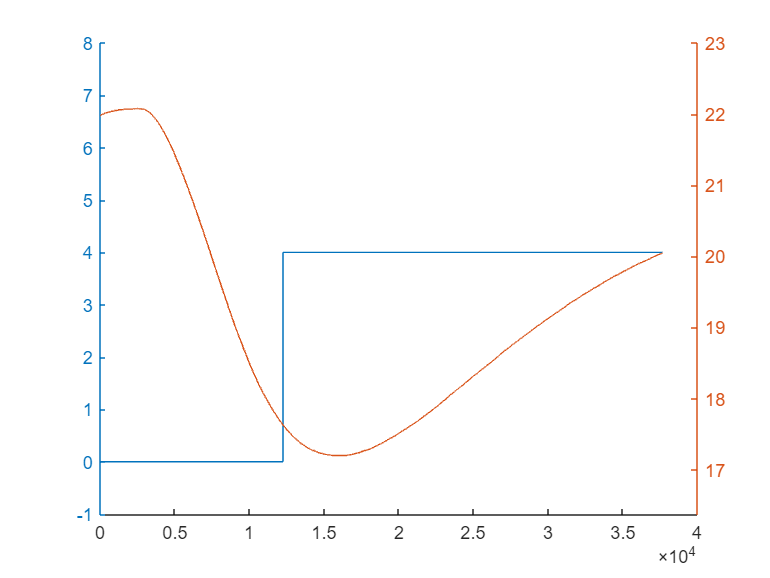

u2 = tab2.regulation_relay_state*4;
u2(1:12249) = 0;
y2 = tab2.temperature_floor;

u2 = u2(1:37656); %Trim down only the usable part
y2 = y2(1:37656);

hold on;
yyaxis left; ylim([-1 8]);
plot(u2);
yyaxis right;
plot(y2);
hold off;

## Data for Evaluating SI

textfile3 = "C:\Users\hdt.OJ\OneDrive - OJ Electronics A S\Thesis\report\data\Test 3\si.csv";
tab3 = loadDataSource(textfile3);

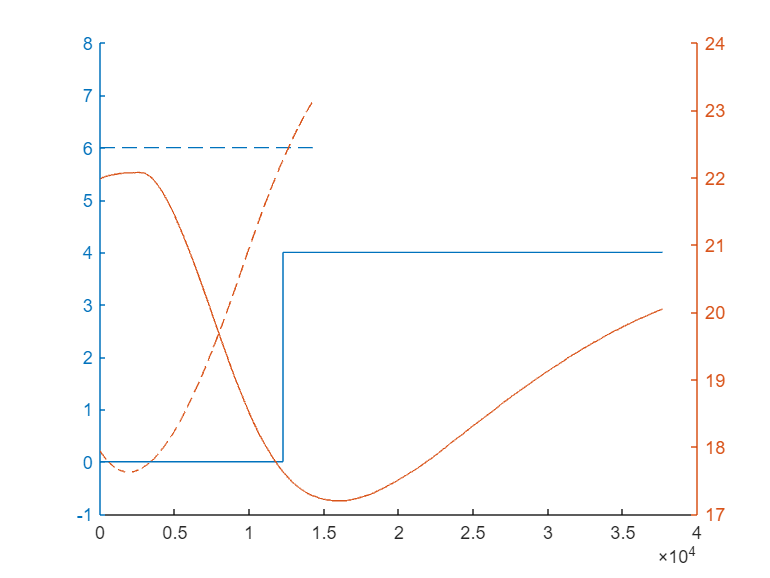


u3 = tab3.regulation_relay_state;
u3(1:end) = 6;
y3 = tab3.temperature_floor;

hold on;
yyaxis left; ylim([-1 8]);
plot(u3);
yyaxis right;
plot(y3);
hold off;